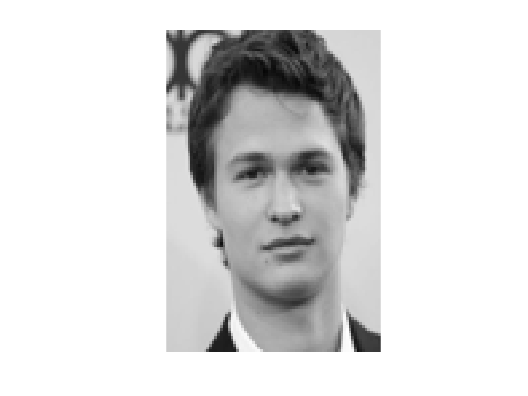

clc
clear
close all
m = 120;
n = 80;
n_images = 5;
images = zeros(m,n,n_images);
image1 = rgb2gray(imresize(imread('ansel_elgort1.jpg'),[m,n]));
images(:,:,1) = image1;
imshow(image1);

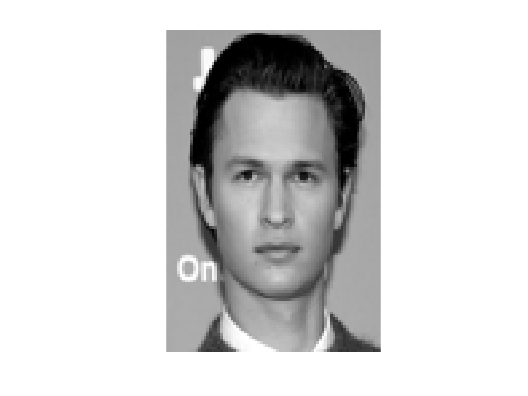

image2 = rgb2gray(imresize(imread('ansel_elgort2.jpg'),[m,n]));
images(:,:,2) = image2;
imshow(image2);

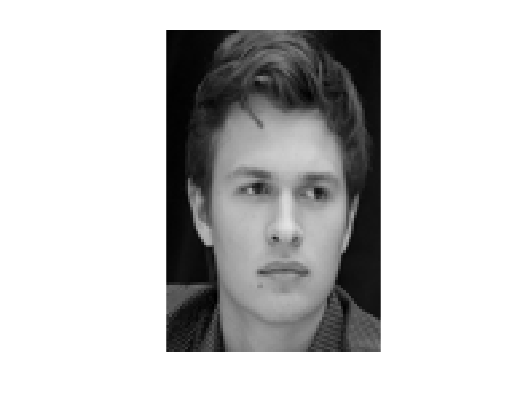

image3 = rgb2gray(imresize(imread('ansel_elgort3.jpg'),[m,n]));
images(:,:,3) = image3;
imshow(image3);

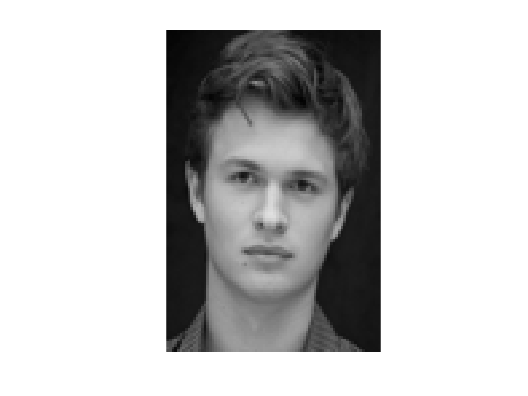

image4 = rgb2gray(imresize(imread('ansel_elgort4.jpg'),[m,n]));
images(:,:,4) = image4;
imshow(image4);

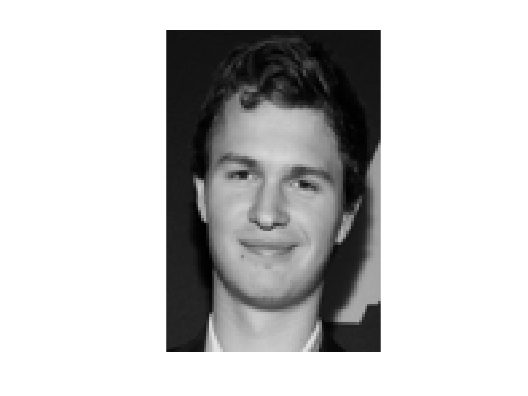

image5 = rgb2gray(imresize(imread('ansel_elgort5.jpg'),[m,n]));
images(:,:,5) = image5;
imshow(image5);

## Prueba imagen normal

fam1 = matriz_a(n_images, m, n, images);

## Cálculo de la matriz transpuesta

A1 = transpose(fam1);

## Cálcular C ( A.t * A)

C1 = A1 * fam1;

## EigenValues

[V1,D1] = eigs(C1,20);

## Reconstrucción de las imágenes del EigenVector

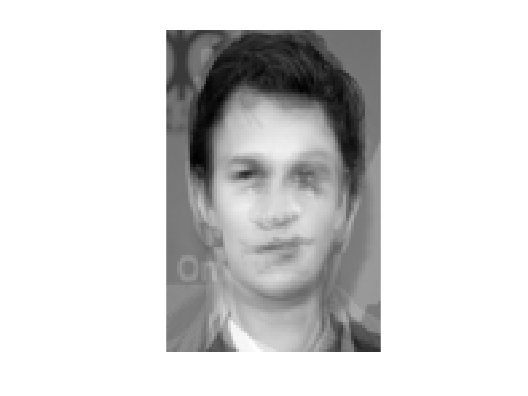

mat1 = zeros(m,n,20);
for i = 1:20
    image = transpose(reshape(V1(:,i),[n,m]));
    mat1(:,:,i) = image;
end

imshow(mat1(:,:,1),[])

## Imágen de prueba

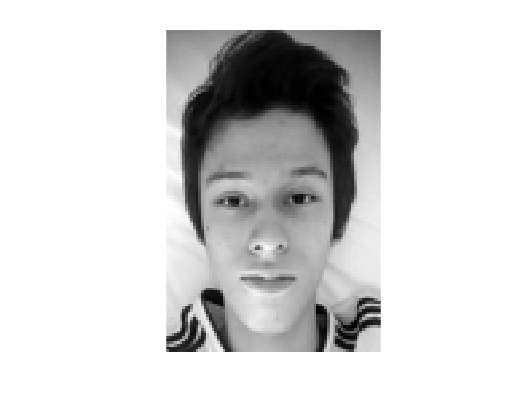

test_img = double(rgb2gray(imresize(imread('luis.jpg'),[m,n])));
imshow(test_img,[])

test_v = reshape(transpose(test_img),[1,m*n]);

p = test_v * V1;

X = V1 * transpose(p);

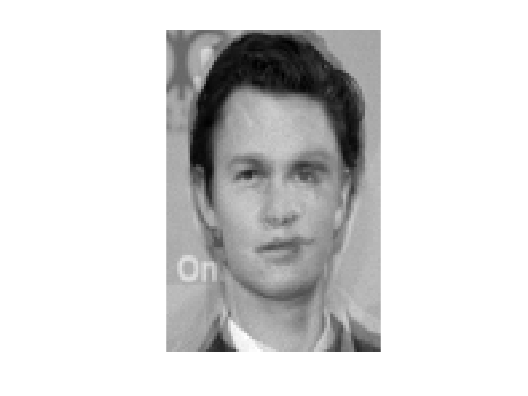

image_r = transpose(reshape(X,[n,m]));
imshow(image_r,[])

## Calcular el error

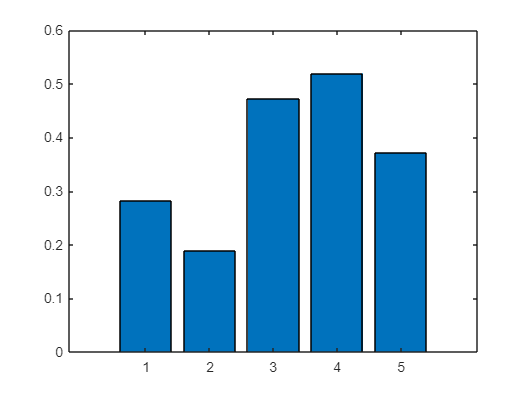

errors = calcular_error(fam1, V1, test_v);
bar(errors)

mean(errors)

ans = 0.3668

TestImages = load('ImagenesProyPID2022.mat')

TestImages = struct with fields:
        Images: {6×5 cell}
    TestImages: {[120×80 double]  [120×80 double]  [120×80 double]  [120×80 double]  [120×80 double]  [120×80 double]}


## Famosos 1

image1 = im2gray(TestImages.Images{1,1});
images(:,:,1) = image1;
image2 = im2gray(TestImages.Images{1,2});
images(:,:,2) = image2;
image3 = im2gray(TestImages.Images{1,3});
images(:,:,3) = image3;
image4 = im2gray(TestImages.Images{1,4});
images(:,:,4) = image4;
image5 = im2gray(TestImages.Images{2,5});
images(:,:,5) = image5;

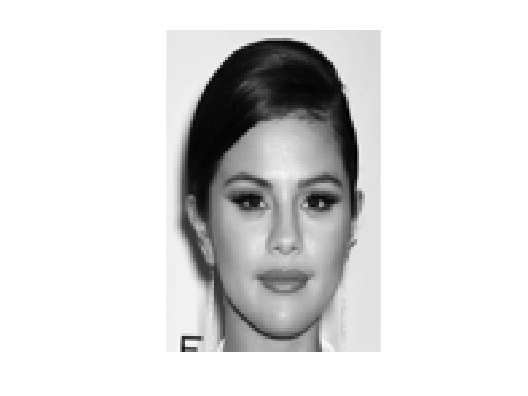

imshow(image1,[])

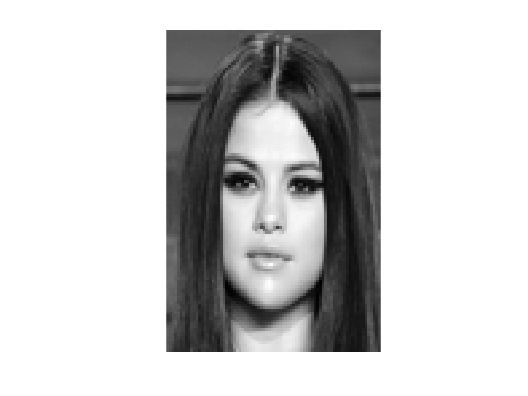

imshow(image2,[])

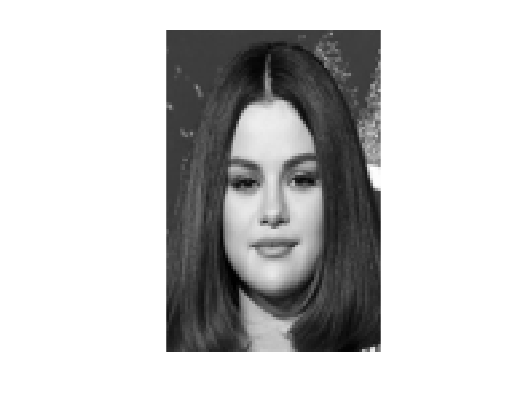

imshow(image3,[])

## Prueba imagen normal

fam1 = matriz_a(n_images, m, n, images);

## Cálculo de la matriz transpuesta

A1 = transpose(fam1);

## Cálcular C ( A.t * A)

C1 = A1 * fam1;

## EigenValues

[V1,D1] = eigs(C1,20);

## Reconstrucción de las imágenes del EigenVector

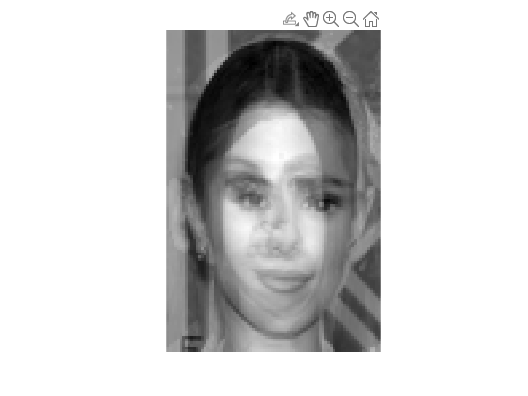

mat1 = zeros(m,n,20);
for i = 1:20
    image = transpose(reshape(V1(:,i),[n,m]));
    mat1(:,:,i) = image;
end

imshow(mat1(:,:,1),[])

## Imágen de prueba

test_img = double(rgb2gray(imresize(imread('luis.jpg'),[m,n])));
imshow(test_img,[])

test_v = reshape(transpose(test_img),[1,m*n]);

p = test_v * V1;

X = V1 * transpose(p);

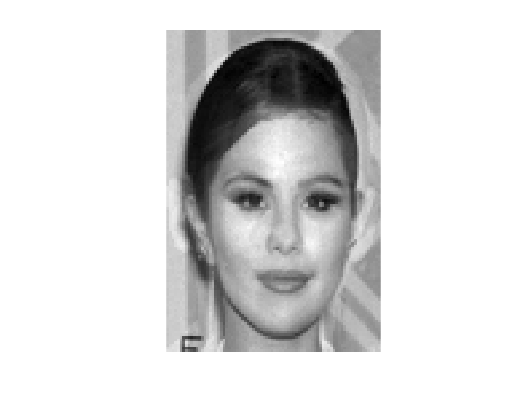

image_r = transpose(reshape(X,[n,m]));
imshow(image_r,[])

## Calcular el error

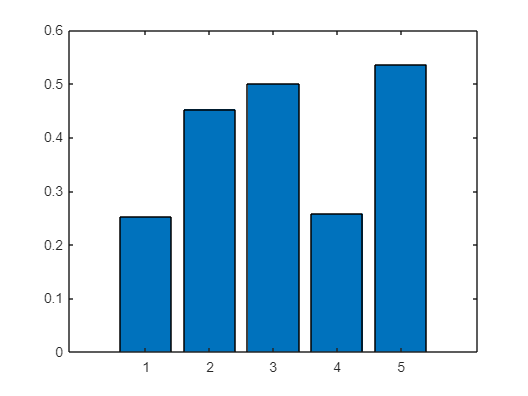

errors = calcular_error(fam1, V1, test_v);
bar(errors)

mean(errors)

ans = 0.3996

## Famosos 2

image1 = im2gray(TestImages.Images{2,1});
images(:,:,1) = image1;
image2 = im2gray(TestImages.Images{2,2});
images(:,:,2) = image2;
image3 = im2gray(TestImages.Images{2,3});
images(:,:,3) = image3;
image4 = im2gray(TestImages.Images{2,4});
images(:,:,4) = image4;
image5 = im2gray(TestImages.Images{2,5});
images(:,:,5) = image5;

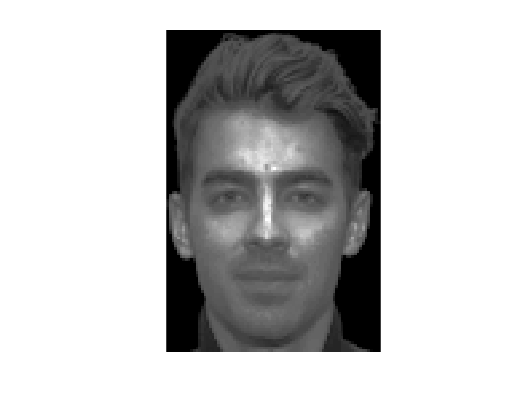

imshow(image1,[])

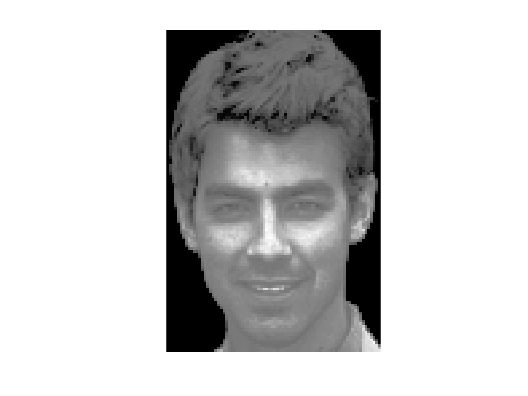

imshow(image2,[])

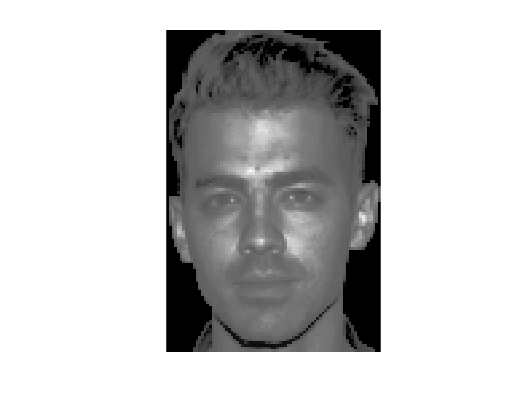

imshow(image3,[])

## Prueba imagen normal

fam1 = matriz_a(n_images, m, n, images);

## Cálculo de la matriz transpuesta

A1 = transpose(fam1);

## Cálcular C ( A.t * A)

C1 = A1 * fam1;

## EigenValues

[V1,D1] = eigs(C1,20);

## Reconstrucción de las imágenes del EigenVector

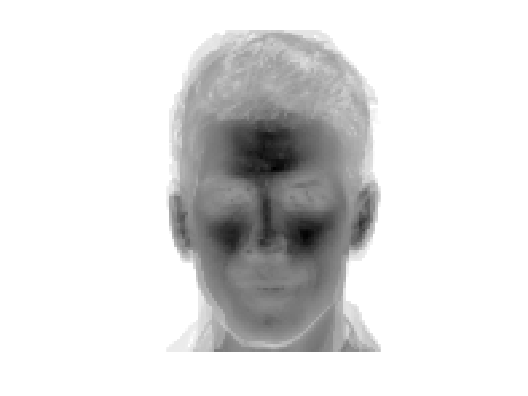

mat1 = zeros(m,n,20);
for i = 1:20
    image = transpose(reshape(V1(:,i),[n,m]));
    mat1(:,:,i) = image;
end

imshow(mat1(:,:,1),[])

## Imágen de prueba

test_img = double(rgb2gray(imresize(imread('luis.jpg'),[m,n])));
imshow(test_img,[])

test_v = reshape(transpose(test_img),[1,m*n]);

p = test_v * V1;

X = V1 * transpose(p);

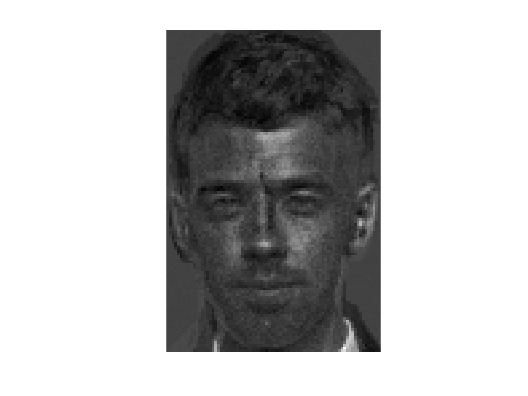

image_r = transpose(reshape(X,[n,m]));
imshow(image_r,[])

## Calcular el error

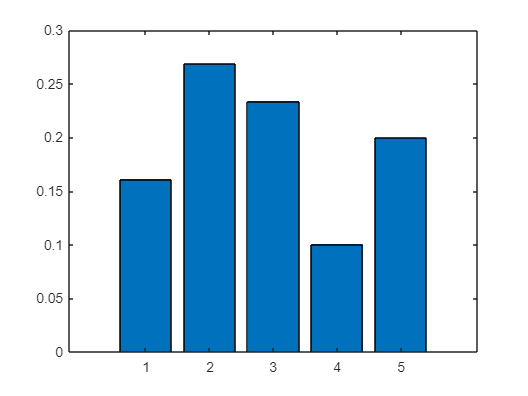

errors = calcular_error(fam1, V1, test_v);
bar(errors)

mean(errors)

ans = 0.1928

## Famoso 3

image1 = im2gray(TestImages.Images{3,1});
images(:,:,1) = image1;
image2 = im2gray(TestImages.Images{3,2});
images(:,:,2) = image2;
image3 = im2gray(TestImages.Images{3,3});
images(:,:,3) = image3;
image4 = im2gray(TestImages.Images{3,4});
images(:,:,4) = image4;
image5 = im2gray(TestImages.Images{3,5});
images(:,:,5) = image5;

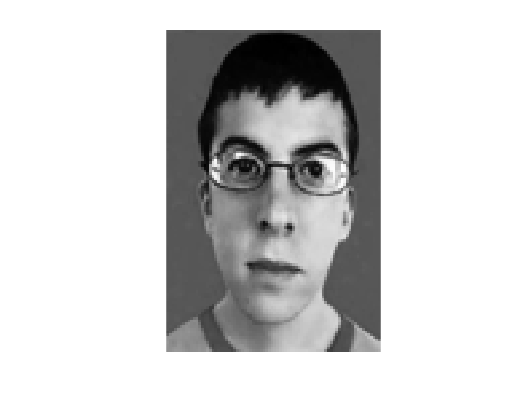

imshow(image1,[])

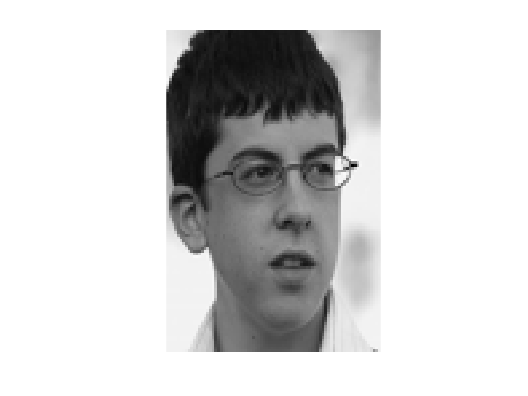

imshow(image2,[])

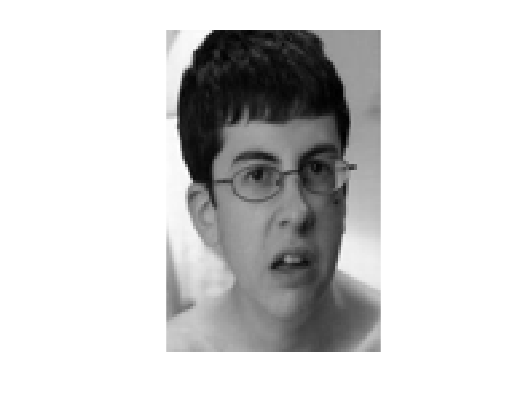

imshow(image3,[])

## Prueba imagen normal

fam1 = matriz_a(n_images, m, n, images);

## Cálculo de la matriz transpuesta

A1 = transpose(fam1);

## Cálcular C ( A.t * A)

C1 = A1 * fam1;

## EigenValues

[V1,D1] = eigs(C1,20);

## Reconstrucción de las imágenes del EigenVector

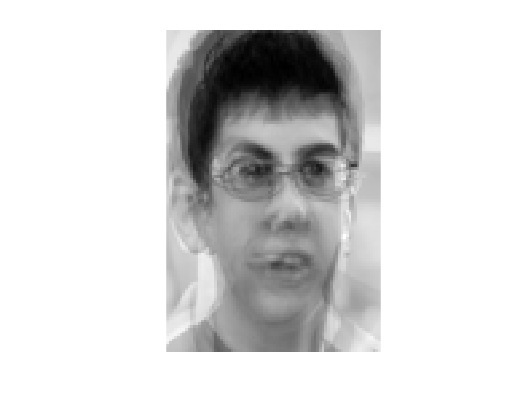

mat1 = zeros(m,n,20);
for i = 1:20
    image = transpose(reshape(V1(:,i),[n,m]));
    mat1(:,:,i) = image;
end

imshow(mat1(:,:,1),[])

## Imágen de prueba

test_img = double(rgb2gray(imresize(imread('luis.jpg'),[m,n])));
imshow(test_img,[])

test_v = reshape(transpose(test_img),[1,m*n]);

p = test_v * V1;

X = V1 * transpose(p);

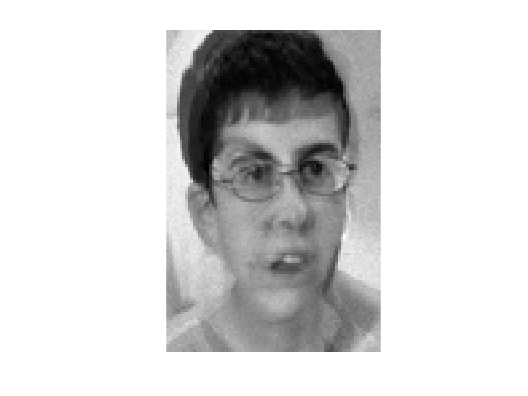

image_r = transpose(reshape(X,[n,m]));
imshow(image_r,[])

## Calcular el error

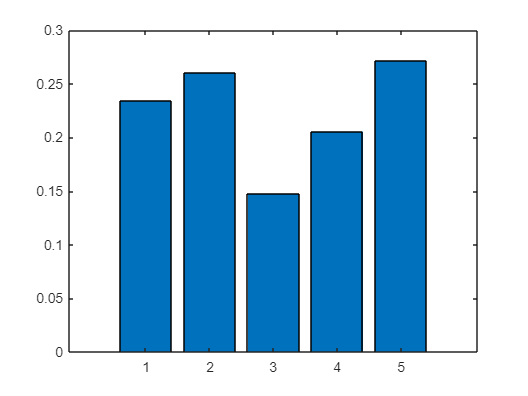

errors = calcular_error(fam1, V1, test_v);
bar(errors)

mean(errors)

ans = 0.2239

## Famoso 4

image1 = im2gray(TestImages.Images{4,1});
images(:,:,1) = image1;
image2 = im2gray(TestImages.Images{4,2});
images(:,:,2) = image2;
image3 = im2gray(TestImages.Images{4,3});
images(:,:,3) = image3;
image4 = im2gray(TestImages.Images{4,4});
images(:,:,4) = image4;
image5 = im2gray(TestImages.Images{4,5});
images(:,:,5) = image5;

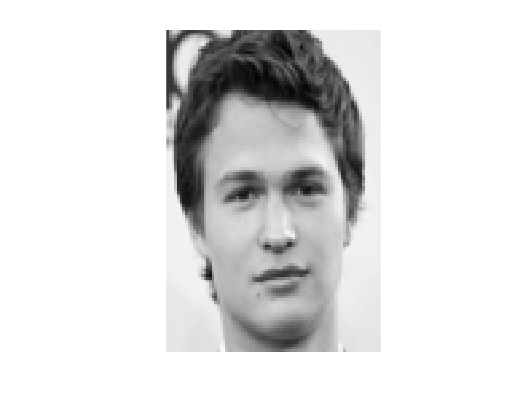

imshow(image1,[])

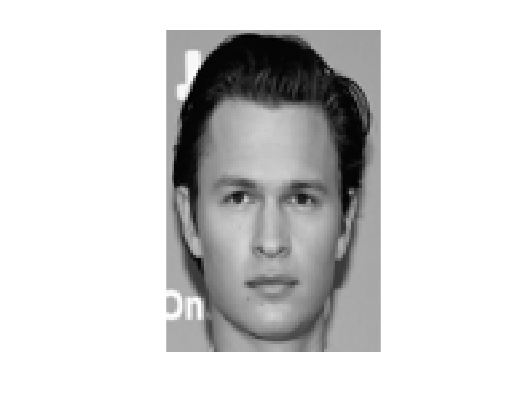

imshow(image2,[])

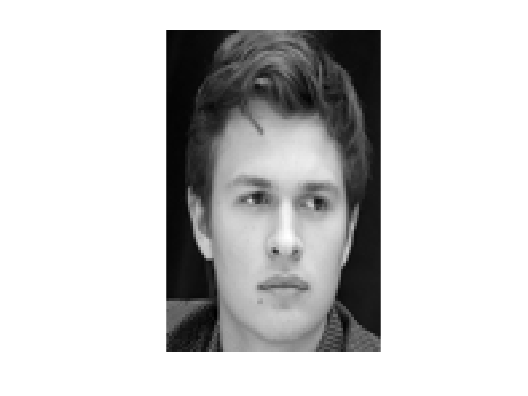

imshow(image3,[])

## Prueba imagen normal

fam1 = matriz_a(n_images, m, n, images);

## Cálculo de la matriz transpuesta

A1 = transpose(fam1);

## Cálcular C ( A.t * A)

C1 = A1 * fam1;

## EigenValues

[V1,D1] = eigs(C1,20);

## Reconstrucción de las imágenes del EigenVector

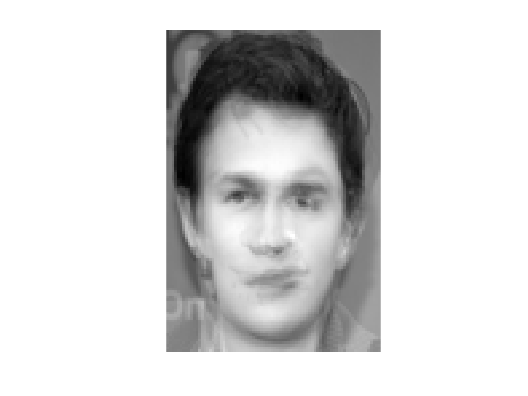

mat1 = zeros(m,n,20);
for i = 1:20
    image = transpose(reshape(V1(:,i),[n,m]));
    mat1(:,:,i) = image;
end

imshow(mat1(:,:,1),[])

## Imágen de prueba

test_img = double(rgb2gray(imresize(imread('luis.jpg'),[m,n])));
imshow(test_img,[])

test_v = reshape(transpose(test_img),[1,m*n]);

p = test_v * V1;

X = V1 * transpose(p);

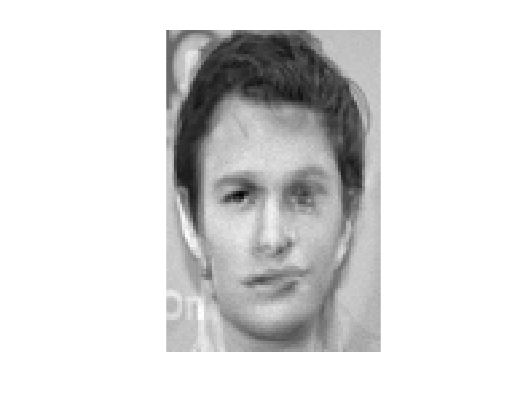

image_r = transpose(reshape(X,[n,m]));
imshow(image_r,[])

## Calcular el error

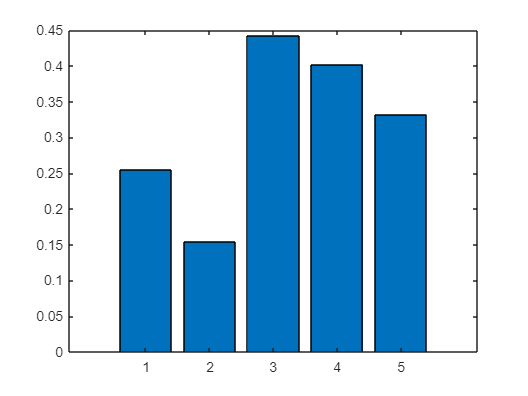

errors = calcular_error(fam1, V1, test_v);
bar(errors)

mean(errors)

ans = 0.3171

## Famoso 5

image1 = im2gray(TestImages.Images{5,1});
images(:,:,1) = image1;
image2 = im2gray(TestImages.Images{5,2});
images(:,:,2) = image2;
image3 = im2gray(TestImages.Images{5,3});
images(:,:,3) = image3;
image4 = im2gray(TestImages.Images{5,4});
images(:,:,4) = image4;
image5 = im2gray(TestImages.Images{5,5});
images(:,:,5) = image5;

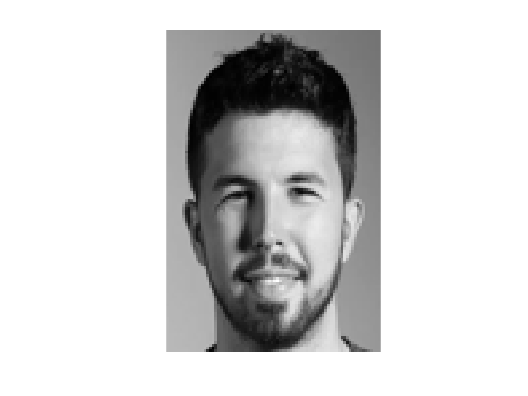

imshow(image1,[])

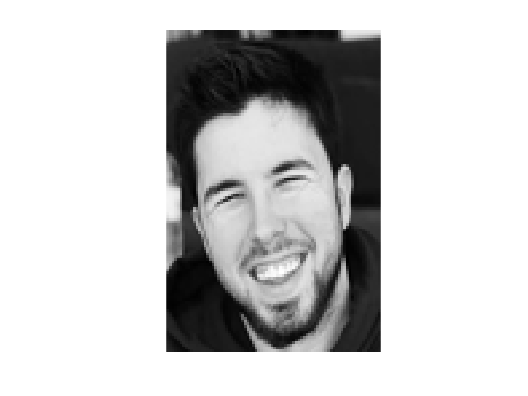

imshow(image2,[])

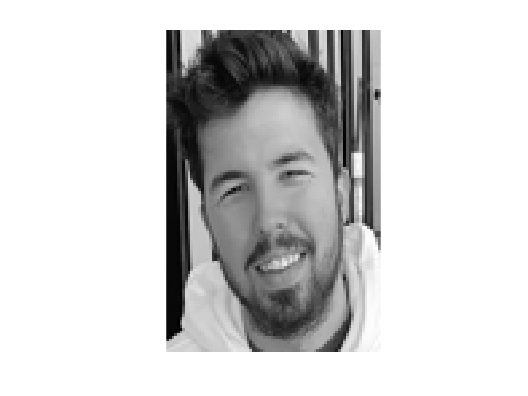

imshow(image3,[])

## Prueba imagen normal

fam1 = matriz_a(n_images, m, n, images);

## Cálculo de la matriz transpuesta

A1 = transpose(fam1);

## Cálcular C ( A.t * A)

C1 = A1 * fam1;

## EigenValues

[V1,D1] = eigs(C1,20);

## Reconstrucción de las imágenes del EigenVector

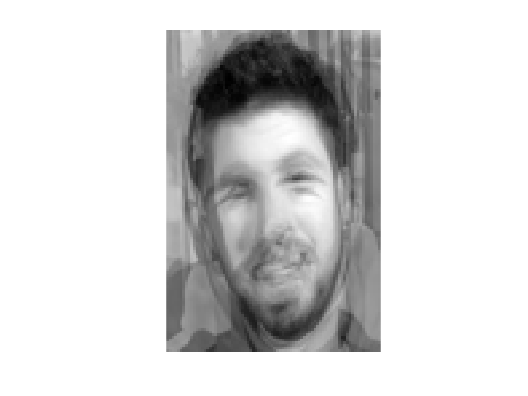

mat1 = zeros(m,n,20);
for i = 1:20
    image = transpose(reshape(V1(:,i),[n,m]));
    mat1(:,:,i) = image;
end

imshow(mat1(:,:,1),[])

## Imágen de prueba

test_img = double(rgb2gray(imresize(imread('luis.jpg'),[m,n])));
imshow(test_img,[])

test_v = reshape(transpose(test_img),[1,m*n]);

p = test_v * V1;

X = V1 * transpose(p);

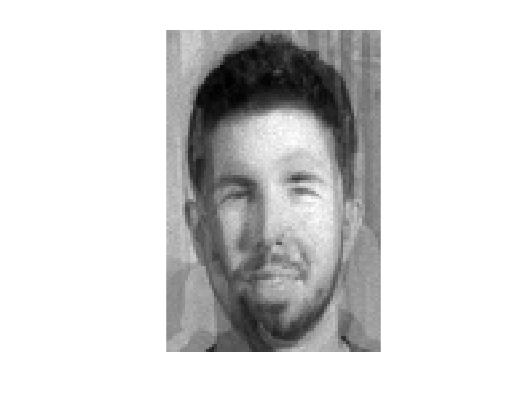

image_r = transpose(reshape(X,[n,m]));
imshow(image_r,[])

## Calcular el error

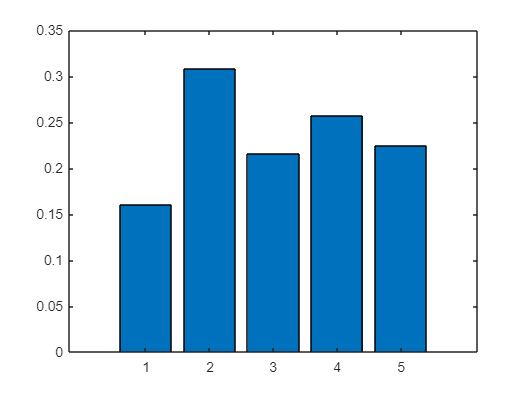

errors = calcular_error(fam1, V1, test_v);
bar(errors)

mean(errors)

ans = 0.2331